# Practice 0

# Part 0

# A Simple Example 

Simulation random variables

Increasing the sample size improves the estimation accuracy 

This version 12/09/2024

Code

% Generate n=100 student-t(nu) random numbers
% set seed for random number generator
rng(0)
n_100 = 100;
% t nu degrees of freedom
nu=5

nu = 5

% vector r contains random numbers
r_100 = trnd(nu,n_100,1);
% Compute mean 
me_100 = mean(r_100)

me_100 = 0.1466

% Compute theoretical variance (df/(df-2)) 
tvar= (nu/(nu-2))

tvar = 1.6667

% Compute sample variance  
s2_100= var(r_100)

s2_100 = 2.3201

% Compare sample and theoretical variance
dif_100= (tvar-s2_100)/s2_100

dif_100 = -0.2816

% With sample size 100 the sample variance missestimates the theoretical variance
% Increase sample size
% Generate n student-t(nu) random numbers
% set seed for random number generator
rng(0)
n_1000 = 1000;
r_1000 = trnd(nu,n_1000,1);
% Compute mean 
me_1000 = mean(r_1000)

me_1000 = -0.0483

% Compute theoretical variance (df/(df-2)) 
tvar= (nu/(nu-2))

tvar = 1.6667

% Compute sample variance  
s2_1000= var(r_1000)

s2_1000 = 1.5550

dif_1000= (tvar-s2_1000)/s2_1000

dif_1000 = 0.0718

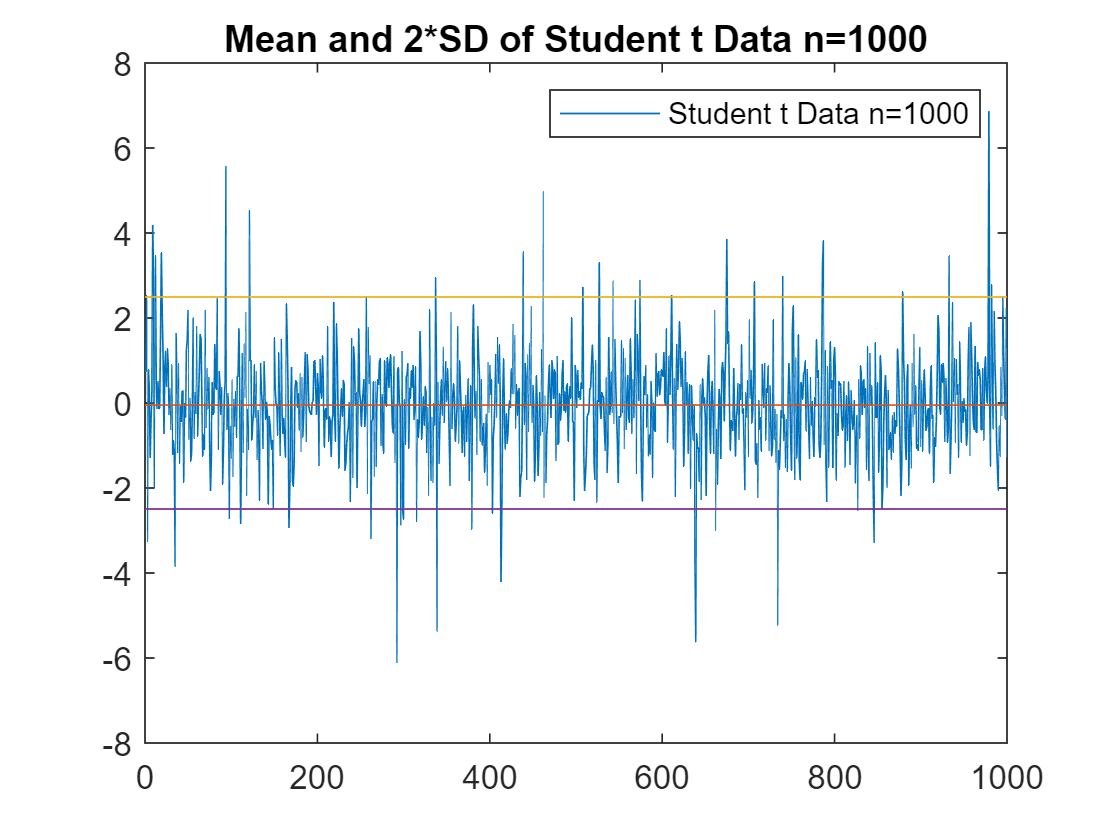

% With sample size 1000, the sample variance is closer to the theoretical variance
% Plot data
s1_1000=std(r_1000); % Sample Standard deviation
plot(r_1000)
hold on
plot([0,n_1000],[me_1000,me_1000])
plot([0,n_1000],[2*s1_1000,2*s1_1000])
plot([0,n_1000],[-2*s1_1000,-2*s1_1000])
hold off
title('Mean and 2*SD of Student t Data n=1000')
% Histogram and fit
legend('Student t Data n=1000')

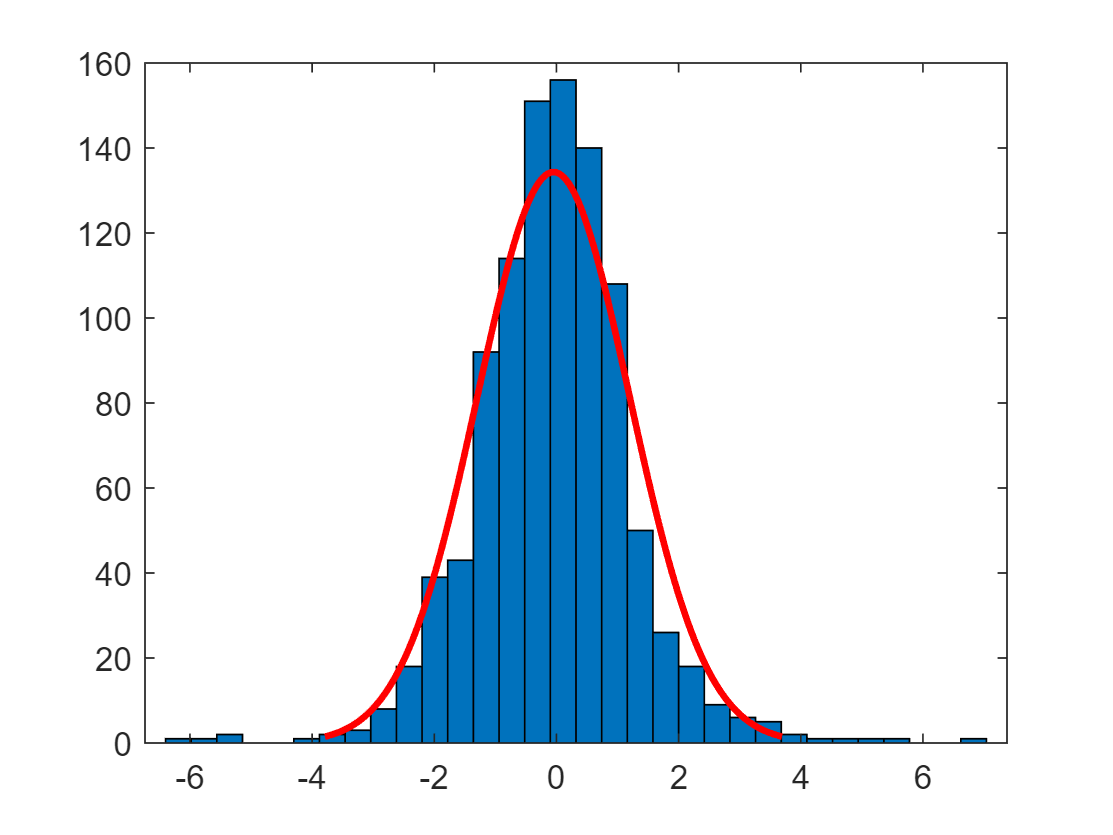

histfit(r_1000)